# Welcome to PECUZAL attractor reconstruction for MATLAB

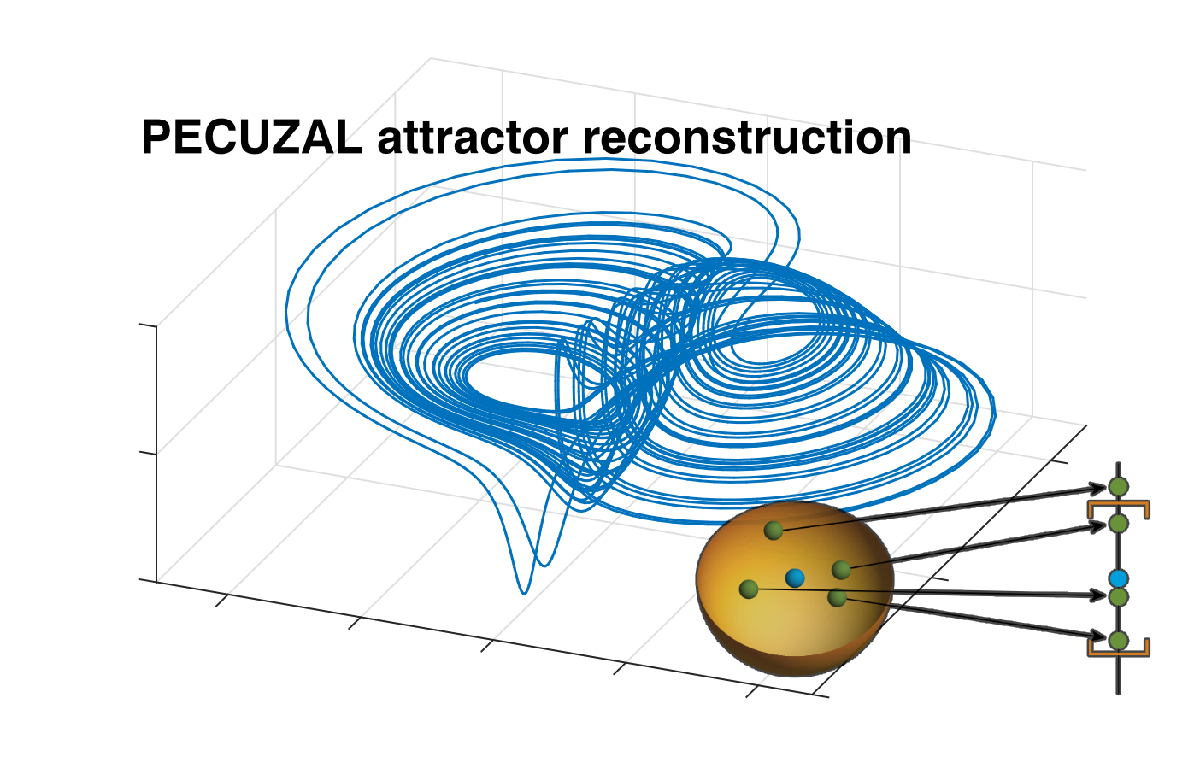

PECUZAL is an automatic approach for embedding time series in MATLAB. It is based on the paper [Kraemer et al. 2020](https://arxiv.org/abs/2011.07040) (Open Source), where the functionality is explained in detail. Here we give an introduction to its easy usage in three examples. Enjoy Embedding! 

Note, that you are welcome to use this Live-Script on your local machine. Download the file from the [git repository](https://github.com/hkraemer/PECUZAL_Matlab/blob/main/docs/pecuzal_examples.mlx?raw=true).

### Installation

There are two ways of using the proposed PECUZAL method:

- Install as Toolbox. This is the easiest way and allows the usage of the the function `pecuzal_embedding` independently from your current working directory. It is available like a built-in MATLAB-function and you do not have to copy any files etc. For this simply [download the 'pecuzal-embedding.mltbx' from this repository](https://github.com/hkraemer/PECUZAL_Matlab/blob/main/pecuzal-embedding.mltbx) or from MATLAB-Central (hyperref HERE) and double-click for installation. That's it.

- You can also download this repository and copy the folder into the MATLAB user's directory. This is usually the user's "Documents" folder appended with "MATLAB" (you can find out using the function `userpath`). Add the toolbox by the `addpath` command, e.g., `addpath ~/Documents/MATLAB/PECUZAL_Matlab` on a Linux system. For everyday use, copy this command to a `startup.m` file in the MATLAB user's directory.

### Citing and reference

If you enjoy this tool and find it valuable for your research please cite

- **Kraemer et al., "A unified and automated approach to attractor reconstruction",  **[**arXiv:2011.07040 [physics.data-an]**](https://arxiv.org/abs/2011.07040)**, 2020.**

or as BiBTeX-entry:

`@misc{kraemer2020,`

`    title={A unified and automated approach to attractor reconstruction}, `

`    author={K. H. Kraemer and G. Datseris and J. Kurths and I. Z. Kiss and J. L. Ocampo-Espindola and N. Marwan},    `

`    year={2020},`

`    eprint={2011.07040},`

`    archivePrefix={arXiv},`

`    primaryClass={physics.data-an}`

`    url={https://arxiv.org/abs/2011.07040}`

`    }`

### Basic usage

Let us first take a look at the help of the `pecuzal_embedding` function:

help pecuzal_embedding

  pecuzal_embedding automated phase space reconstruction method.
     
     Y = pecuzal_embedding(X) reconstructs fully automatically the 
     (N-by-M)-matrix Y of phase space vectors from the time series matrix X
     of size (N0-by-M0) where M0 could be 1 (for time series) or larger for
     multivariate time series.
 
     Y = pecuzal_embedding(X, TAU) reconstructs the phase space vectors
     by using vector TAU for which possible delay times the algorithm shall 
     look (default [0:50]).
 
     [Y, TAU_VALS, TS_VALS] = pecuzal_embedding(...) provides a vector of (different) 
     time delays TAU_VALS chosen by the algorithm and a vector TS_VALS with the
     indices between 1 and M0 of chosen time series from matrix X, corresponding to
     the delays TAU_VALS.
 
     [Y, TAU_VALS, TS_VALS, L, E] = pecuzal_embedding(...) provides a vector L
     of L-statistic values for the reconstruction in e

The function expects at least one input argument (a uni- or multivariate time series) and returns the phase space vectors. Several optional parameters, some as (Name, Value)-pairs, can be used fine tune the algorithm. We recommend to stick to the default values first, as described in [kraemer2020], and only parse an adequate Theiler-window, in order to exclude serially correlated time series values from the nearest neighbour search. We will see in the following how that could be done.

#### Univariate example (Rössler system)

We exemplify the proposed embedding method by embedding the *y*-component of the Rössler system with standard parameters 

clear
set(0, 'DefaultAxesFontSize', 14, 'DefaultLineLineWidth', 1) % increase font size and line width for the figures
  
% set parameters for standard Roessler
a = 0.2;
b = 0.2;
c = 5.7;

% Set time series length and sampling
N = 5000;
dt = 0.2;
transient_time = 2500;
tf = (N+transient_time) * dt; 
t = 0:dt:tf;

We define the [Rössler ODE-System](https://en.wikipedia.org/wiki/R%C3%B6ssler_attractor) and solve it to obtain the time series.

% Roessler ODE
roe = @(t,x) [-x(2)-x(3); x(1)+a*x(2); b+x(3)*(x(1)-c)];

% solve the ODE
x0 = [1.; .5; 0.5]; % initial conditions  
[t, x] = ode45(roe, t, x0);

% remove transients
x(1:transient_time+1,:) = [];
t = t(1:end-transient_time-1);

We focus on the *y*-component and compute the auto mutual information (MI), in order to estimate an appropriate Theiler window. This is especially important when dealing with highly sampled datasets. Let us also plot the data and the MI.

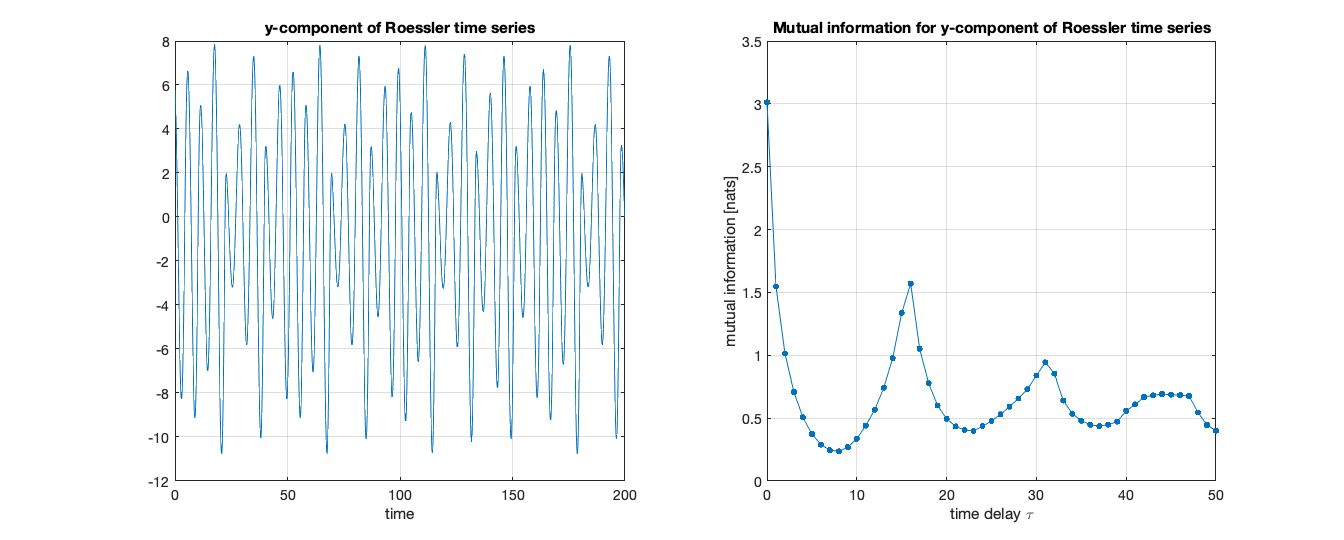

y = x(:,2);  % bind y-component
mi = mutualinformation(y,50); % compute MI

figure('Units', 'normalized', 'Position', [.3 .3 .7 .5])

subplot(1,2,1)
plot(t(1:1000), y(1:1000))
title('y-component of Roessler time series')
xlabel('time')
grid on

subplot(1,2,2)
plot(mi(:,1), mi(:,2), '.-', 'MarkerSize',15)
xlabel('time delay \tau')
ylabel('mutual information [nats]')
title('Mutual information for y-component of Roessler time series')
grid on

Now we are ready to go and call the PECUZAL algorithm `pecuzal_embedding` with a Theiler window determined from the first minimum of the mutual information shown in the above Figure, i.e. `'theiler'=7`, and possible delays ranging in the interval `[0:100]`. 

**NOTE: The following computation will take approximately 1 to 2 minutes (depending on the machine you are running the code on).**

[Y_reconstruct, tau_vals, ts_vals, Ls, E] = pecuzal_embedding(y, 0:100, 'theiler', 7)

Algorithm stopped due to minimum L-value reached. VALID embedding achieved.


Y_reconstruct =     5.7856   -1.4035   -8.2342
    5.3290   -2.8216   -7.8740
    4.6361   -4.1834   -7.1814
    3.7255   -5.4313   -6.1721
    2.6255   -6.5100   -4.8768
    1.3732   -7.3687   -3.3416
    0.0132   -7.9637   -1.6297
   -1.4035   -8.2602    0.1726
   -2.8216   -8.2342    1.9499
   -4.1834   -7.8740    3.5560


tau_vals =      0     7    15


ts_vals =      1     1     1


Ls =    -2.5060   -3.2207   -3.1631


E = 1×3 cell array
    {101×1 double}    {101×1 double}    {101×1 double}


After the computation has finished, the function returns the following note in the console:

*Algorithm stopped due to minimum L-value reached. VALID embedding achieved.*

The matrix `Y_reconstruct` contains the reconstructed trajectory. Since in this example matrix `Y_reconstruct` is a three-column matrix, it corresponds to a three-dimensional phase space trajectory which we can visualize in a 3D plot.

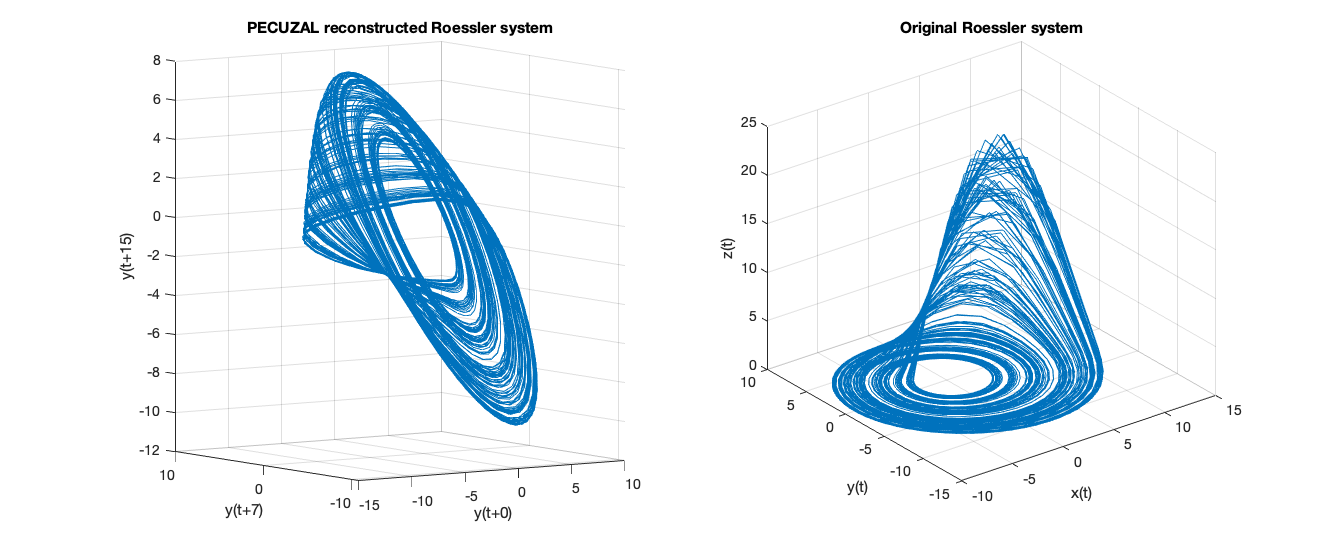

subplot(1,2,1)
plot3(Y_reconstruct(:,1), Y_reconstruct(:,2), Y_reconstruct(:,3))
xlabel(sprintf('y(t+%i)', tau_vals(1)))
ylabel(sprintf('y(t+%i)', tau_vals(2)))
zlabel(sprintf('y(t+%i)', tau_vals(3)))
title('PECUZAL reconstructed Roessler system')
grid on
view([-34.6 5.2])

subplot(1,2,2)
plot3(x(:,1), x(:,2), x(:,3))
xlabel('x(t)')
ylabel('y(t)')
zlabel('z(t)')
title('Original Roessler system')
grid on

For the correct axis labels we used the delay values the PECUZAL algorithm used and which are returned by the output-variable `tau_vals`. 

This means, that the reconstructed trajectory consists of the unlagged time series (here the *y*-component) and two more components with the time series lagged by 7 and 15 sample, respectively. Note the coincidence with the first minimum of the mutual information. The output variable `ts_vals` contains the indices regarding the chosen time series for each delay value stored in `tau_vals`. Because there is only one time series we have used, it is simply

ts_vals

ts_vals =      1     1     1


This output is only needed for the multivariate case, see section Multivariate example (Rössler system).

We can look at the *continuity statistic* the algorithm has used to find the embedding. These statistics for each embedding cycle are provided by the cell array `E`.

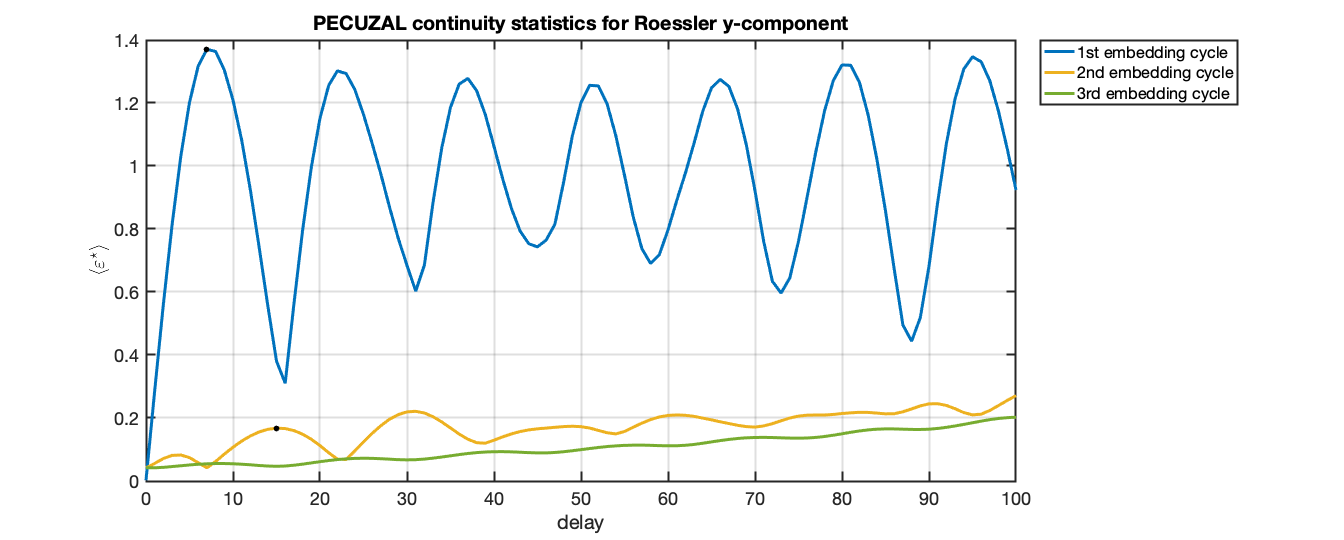

clf
plot(0:length(E{1})-1, E{1}(:,1), 'LineWidth',3), hold on
scatter(tau_vals(2), E{1}(tau_vals(2)+1,1), 'k', 'filled','HandleVisibility',"off")
plot(0:length(E{2})-1, E{2}(:,1), 'LineWidth',3)
scatter(tau_vals(3), E{2}(tau_vals(3)+1,1), 'k', 'filled','HandleVisibility',"off")
plot(0:length(E{3})-1, E{3}(:,1), 'LineWidth',3)
legend('1st embedding cycle', '2nd embedding cycle', '3rd embedding cycle', 'Location', 'northeastoutside')
title('PECUZAL continuity statistics for Roessler y-component')
xlabel('delay')
ylabel('$\langle \varepsilon^\star \rangle$', 'Interpreter', 'latex')
set(gca,'LineWidth',2)
set(gca,'FontSize',18)
grid on

The black markers point at the postitions, where the algorithm picked the delays for the reconstruction from. In the 3rd embedding cycle there is no delay value picked and the algorithm stops, because it cannot minimize the L-statistic further. Its values for each embedding cycle are stored in vector `Ls`:

Ls

Ls =    -2.5060   -3.2207   -3.1631


#### Multivariate example (Rössler system)

Similar to the approach in the preceeding section, we highlight the capability of the proposed embedding method for a multivariate input. The idea is now to use all three time series to the algorithm, even though this is a very far-from-reality example. We already have an adequate representation of the system we want to reconstruct, namely the three time series from the numerical integration. But let us see what PECUZAL suggests for a reconstruction.

Since we have with three time series now, we estimate the Theiler window as the maximum of all Theiler windows of each time series. Again, we estimate the Theiler window by taking the first minimum of the auto mutual information.

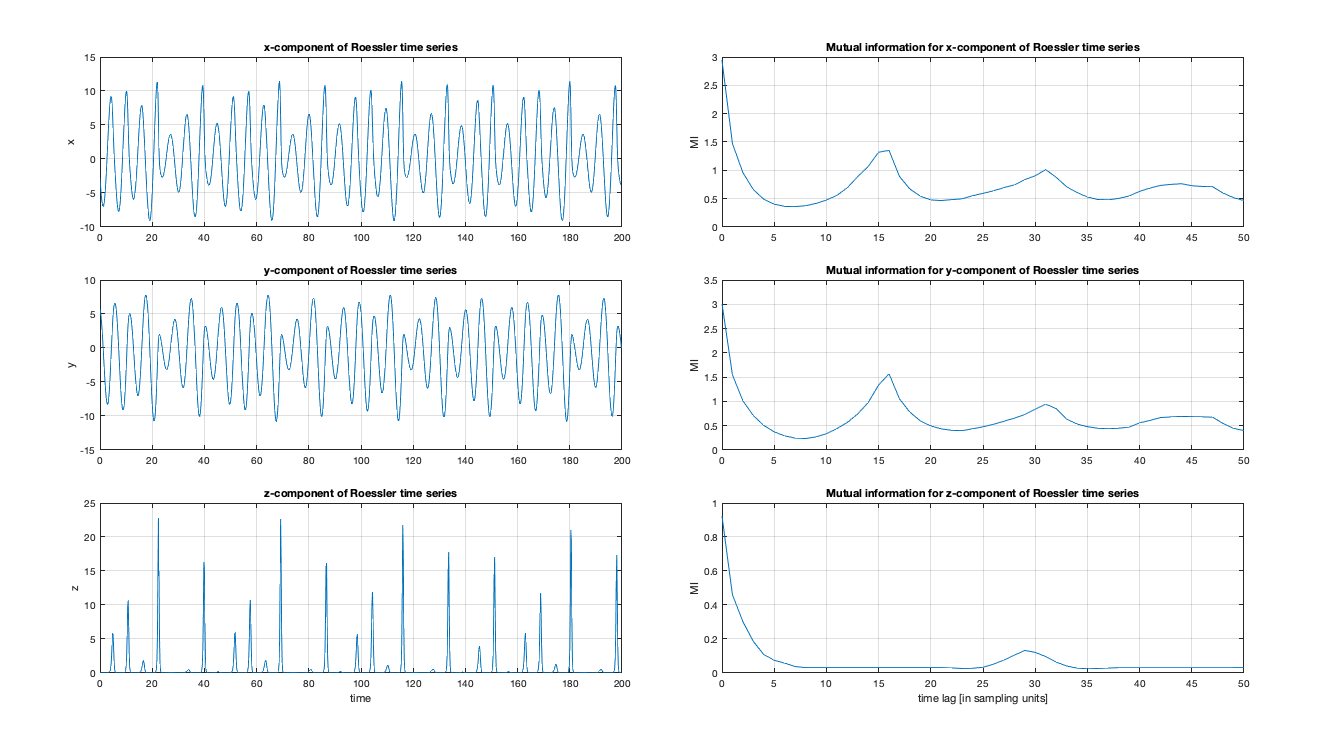

mis = zeros(length(mi),3);
for i = 1:3
    Z = mutualinformation(x(:,i), 50, 0);
    mis(:,i) = Z(:,2);
end
    
figure('Units', 'normalized', 'Position', [.3 .3 .7 .7])
tiledlayout(3,2)

for i = 1:3
    nexttile
    plot(t(1:1000), x(1:1000,i))
    ylabel(char(119+i))
    if i == 3
        xlabel('time')
    end
    title([char(119+i), '-component of Roessler time series'])
    grid on
    
    nexttile
    plot(Z(:,1), mis(:,i))
    ylabel('MI')
    if i == 3
        xlabel('time lag [in sampling units]')
    end
    title(['Mutual information for ', char(119+i), '-component of Roessler time series'])
    grid on 
end

Due to the spikyness of the *z*-component the according auto mutual information yields no meaningful result here. So we stick to the choice of `theiler = 7` and call the PECUZAL algorithm with default optional parameters and possible delays in the interval `[0:100]`.

**NOTE: The following computation will take approximately 5-10 minutes (depending on the machine you are running the code on).**

[Y_reconstruct_m, tau_vals_m, ts_vals_m, Ls_m, E_m] = pecuzal_embedding(x, 0:100, 'theiler', 7)

Algorithm stopped due to minimum L-value reached. VALID embedding achieved.


Y_reconstruct_m =     0.5338    0.1316
    0.4410    0.1199
    0.5116    0.2124
    0.5398    0.4415
    0.6641    0.1196
    0.4638   -0.2591
    0.5212   -0.1237
    0.4305   -0.0173
    0.3317    0.1321
    0.6357   -0.1682


tau_vals_m =      0    23


ts_vals_m =      1     1


Ls_m =    -1.8341   -1.7821


E_m = 1×2 cell array
    {101×1 double}    {101×1 double}


The computation end with the following note in the console:

*Algorithm stopped due to minimum L-value reached. VALID embedding achieved.*

The suggested embedding parameters

tau_vals_m

tau_vals_m =      0     1     3


ts_vals_m

ts_vals_m =      1     2     1


reveal that PECUZAL reconstructs the trajectory `Y_reconstruct_m` from the unlagged *x*-component time series (index 0),  the *y*-component lagged by 1 sample, and finally again the *x*-component but now lagged by 3 samples. As expected the total *L*-value is smaller here than in the univariate case:

L_total_uni = min(Ls)

L_total_uni = -3.2207

L_total_multi = min(Ls_m)

L_total_multi = -3.2426

The reconstructed attractor looks also quite similar to the original one, even though that is not a proper evaluation criterion for the goodness of a reconstruction, see [kraemer2020].

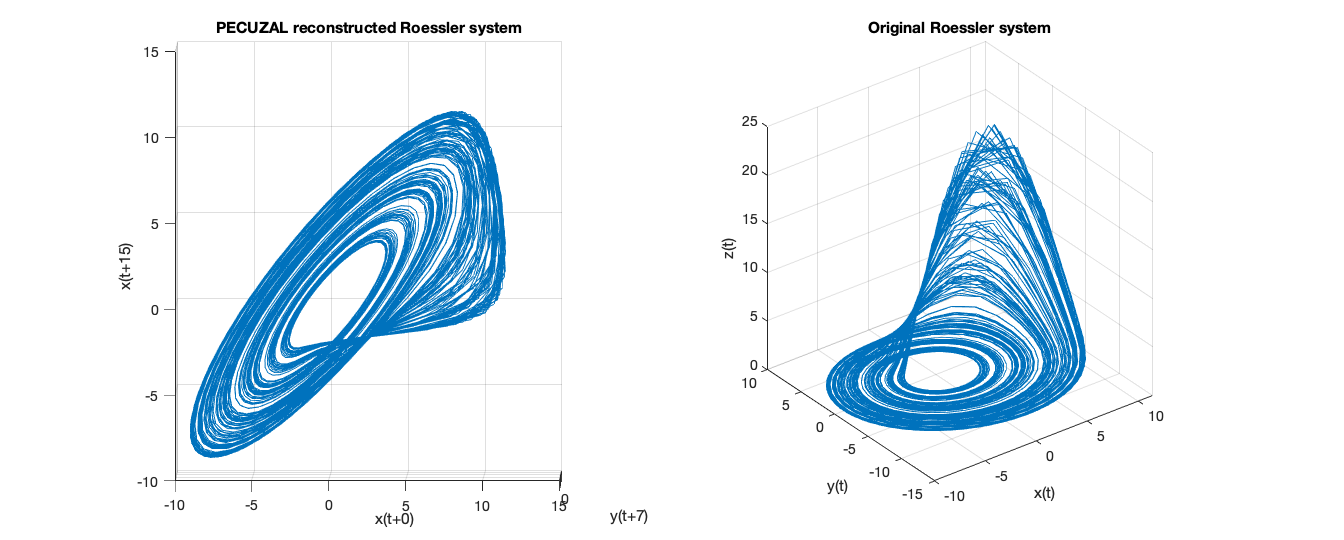

figure('Units','normalized','Position',[.3 .3 .7 .5])

subplot(1,2,1)
plot3(Y_reconstruct_m(:,1), Y_reconstruct_m(:,2), Y_reconstruct_m(:,3))
xlabel(sprintf('%s(t+%i)', char(119+ts_vals_m(1)), tau_vals(1)))
ylabel(sprintf('%s(t+%i)', char(119+ts_vals_m(2)), tau_vals(2)))
zlabel(sprintf('%s(t+%i)', char(119+ts_vals_m(3)), tau_vals(3)))
title('PECUZAL reconstructed Roessler system')
grid on
view([0.4 1.4])

subplot(1,2,2)
plot3(x(:,1), x(:,2), x(:,3))
xlabel('x(t)')
ylabel('y(t)')
zlabel('z(t)')
title('Original Roessler system')
grid on
view([-37.5 30.0])

#### Stochastic source example

Finally we demonstrate how the PECUZAL method works with non-deterministic input data. Therefore, we create a simple AR(1)-process:

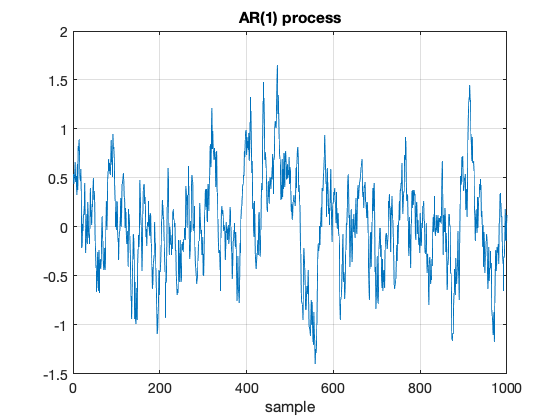

M = 2000; % length of the time series
x = zeros(1,M+10);
x(1) = .2; % intial value
alpha = .9; % auto-correlation parameter
p = .2; % noise amplitude
for i = 2:N+10
    x(i) = alpha*x(i-1) + p*randn;
end
x = x(10:end); % remove transients

figure
plot(1:1000, x(1:1000))
title('AR(1) process')
xlabel('sample')
grid on

When we now call the PECUZAL algorithm

[Y_reconstruct_s, tau_vals_s, ts_vals_s, Ls_s, eps_s] = pecuzal_embedding(x)

Algorithm stopped due to minimum L-value reached. VALID embedding achieved.


Y_reconstruct_s =     0.5338    0.2134
    0.4410    0.3736
    0.5116    0.4951
    0.5398    0.2767
    0.6641    0.3646
    0.4638    0.2490
    0.5212   -0.1444
    0.4305   -0.2506
    0.3317   -0.4197
    0.6357   -0.6565


tau_vals_s =      0    44


ts_vals_s =      1     1


Ls_s =    -1.9648   -1.8719


eps_s = 1×2 cell array
    {51×1 double}    {51×1 double}


 the algorithms stops with the following note in the console:

*Algorithm stopped due to non-decreasing L-value. NO valid embedding achieved.*

This means, the algorithm could not obtain any valid embedding, thus, it values the input data as a non-deterministic source.